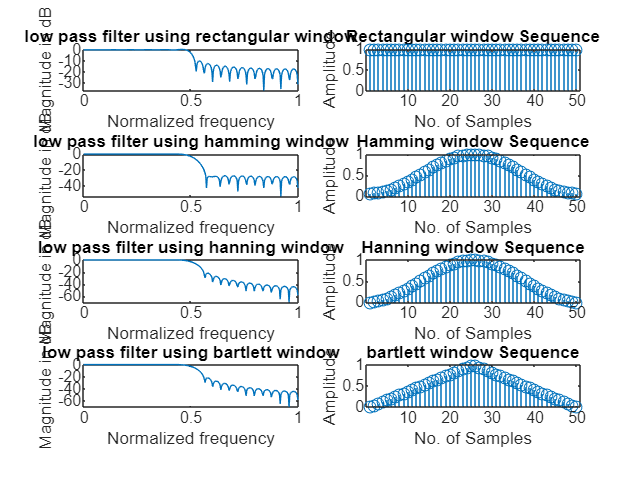

clc;
clear all;
close all;
wc=0.5*pi;

N = input('Enter the value of N=');
alpha = (N-1)/2;
eps = 0.001;
n = 0:1:N-1;
hd = sin(wc*(n-alpha+eps))./(pi*(n-alpha+eps));

wr = boxcar(N);
wh=hamming(N);
wn=hanning(N);
wt=bartlett(N);
hn = hd.*wr';
hn1=hd.*wh';
hn2=hd.*wn';
hn3=hd.*wt';
w = 0:0.01:pi;
h = freqz(hn,1,w);
h1 = freqz(hn1,1,w);
h2 = freqz(hn2,1,w);
h3=freqz(hn3,1,w);
subplot(4,2,1);
plot(w/pi,10*log10(abs(h)));
title('low pass filter using rectangular window');
xlabel('Normalized frequency');
ylabel('Magnitude in dB');
subplot(4,2,2);
stem(wr);
title('Rectangular window Sequence');
xlabel('No. of Samples');
ylabel('Amplitude');
subplot(4,2,3);
plot(w/pi,10*log10(abs(h1)));
title('low pass filter using hamming window');
xlabel('Normalized frequency');
ylabel('Magnitude in dB');
subplot(4,2,4);
stem(wh);
title('Hamming window Sequence');
xlabel('No. of Samples');
ylabel('Amplitude');
subplot(4,2,5);
plot(w/pi,10*log10(abs(h2)));
title('low pass filter using hanning window');
xlabel('Normalized frequency');
ylabel('Magnitude in dB');
subplot(4,2,6);
stem(wn);
title('Hanning window Sequence');
xlabel('No. of Samples');
ylabel('Amplitude');
subplot(4,2,7);
plot(w/pi,10*log10(abs(h2)));
title('low pass filter using bartlett window');
xlabel('Normalized frequency');
ylabel('Magnitude in dB');
subplot(4,2,8);
stem(wt);
title('bartlett window Sequence');
xlabel('No. of Samples');
ylabel('Amplitude');